# Level

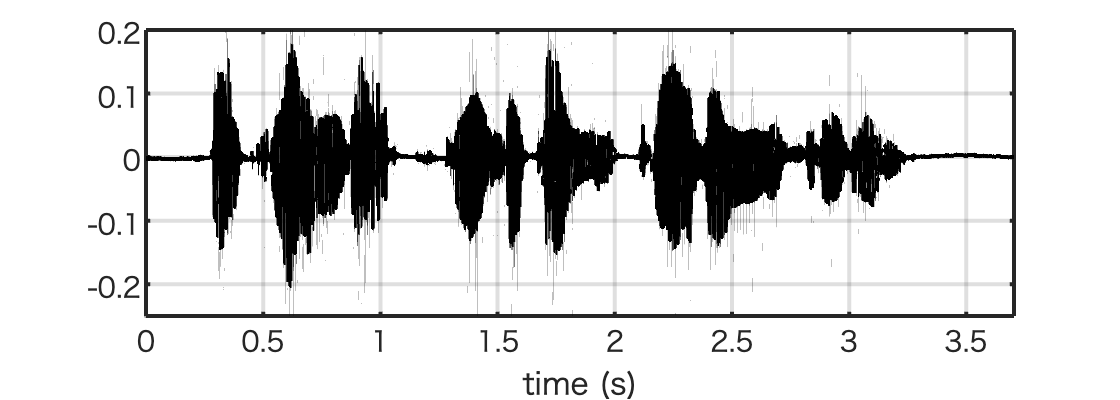

[xOrg,fs] = audioread("bak48kv3T.wav");
figure;
set(gcf,"position",[680 458 560 200])
fftl = length(xOrg);
x = zeros(fftl,1);
x(1:length(xOrg)) = xOrg;
tx = (1:length(x))'/fs;
fx = (0:fftl-1)'/fftl*fs;
plot(tx,x,"k","LineWidth",2);grid on
axis([0 tx(end) -0.25 0.2])
set(gca,"LineWidth",2,"fontsize",14)
xlabel("time (s)")
print -dpdf  bak48kRawWave.pdf

%figure;semilogx(fx,20*log10(abs(fft(x))));grid on;
%set(gca,"xlim",[10 fs/2])

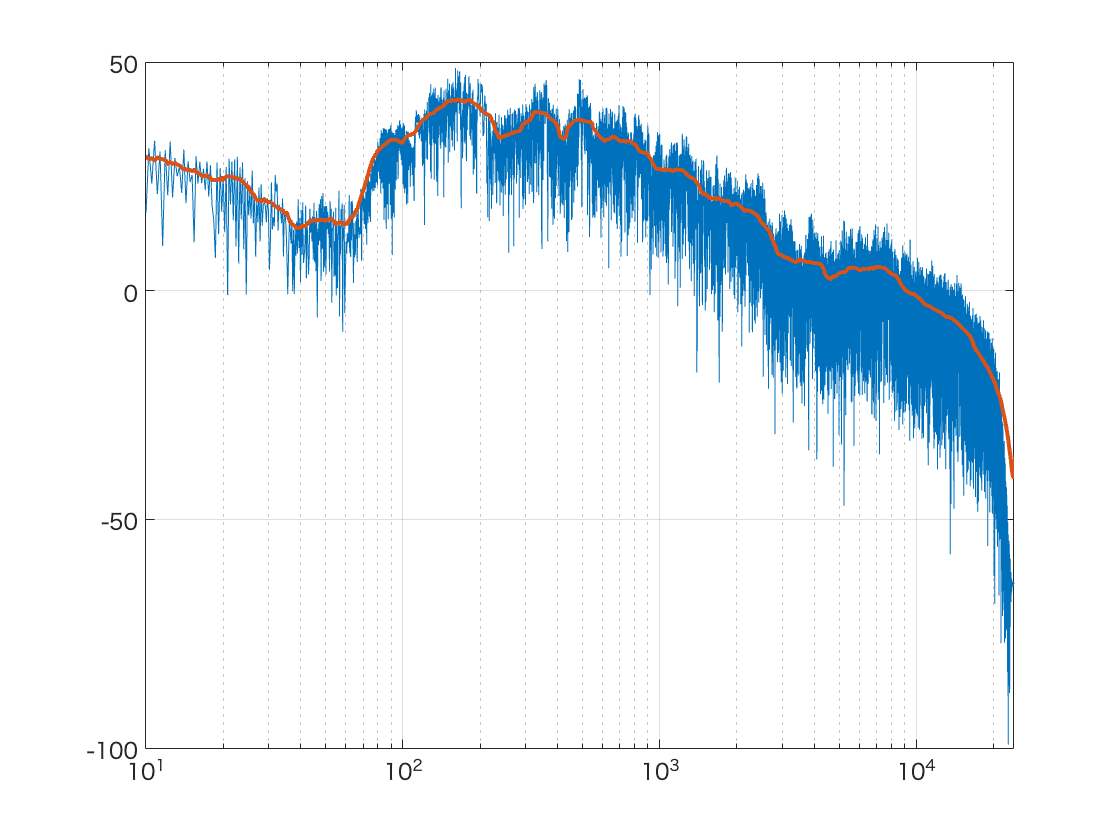

fxH = fx*2^(1/6);
fxL = fx*2^(-1/6);
bw = fxH-fxL;
bw(1) = bw(2);
pwr = abs(fft(x)).^2;
cumPwr = cumsum(pwr*fx(2));
th0 = (interp1(fx,cumPwr,fxH,"linear","extrap")-interp1(fx,cumPwr,fxL,"linear","extrap"))./bw;
figure;semilogx(fx,20*log10(abs(fft(x))));grid on;
hold all
semilogx(fx,10*log10(th0),LineWidth=2);grid on;
set(gca,"xlim",[10 fs/2])

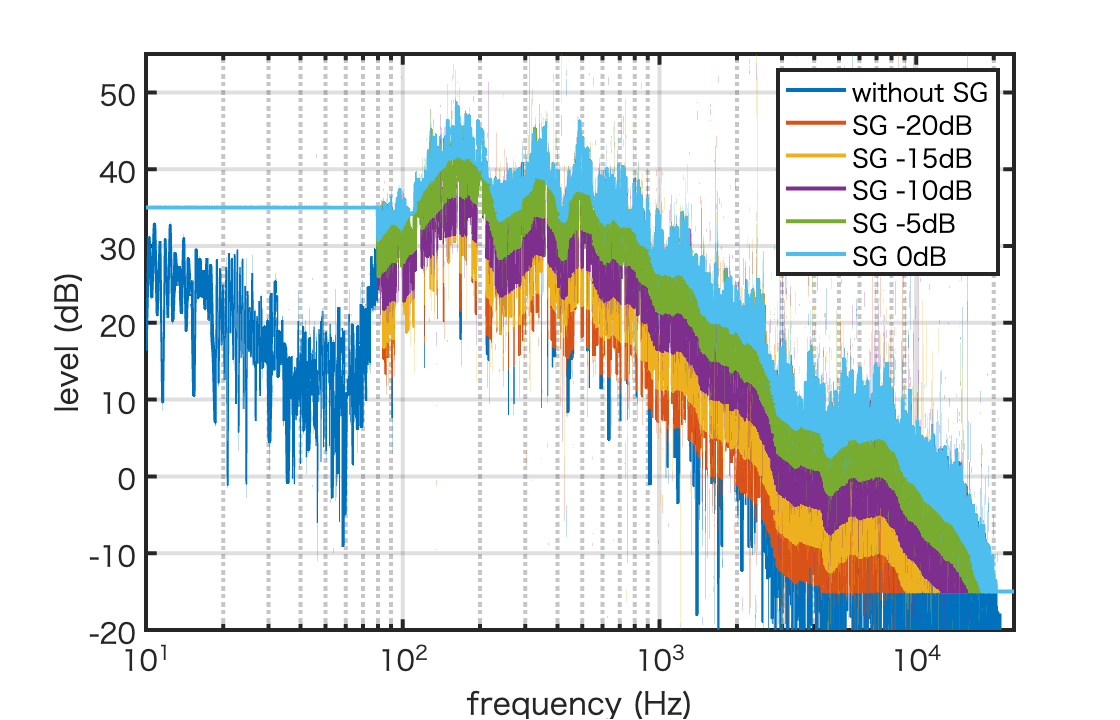

thLvl = [0 5 10 15 20];
thBase = sqrt(th0);
r = abs(fft(x));
expp = fft(x) ./ r;
figure;
set(gcf, "Position", [680         458         560         360])
%get(gcf, "Position")
semilogx(fx,20*log10(abs(fft(x))),"linewidth",2);grid on;
axis([10 fs/2 -20 55])
hold all
for ii = length(thLvl):-1:1
    tmpLvl = thLvl(ii);
    tmpTh = thBase*10^(-tmpLvl/20);
    tmpTh(fx<80) = max(10^(35/20),tmpTh(fx<80));
    tmpTh = max(10^(-15/20),tmpTh);
    ampSG = max(r,tmpTh);
    xFSG = ampSG.*expp;
    xFSG(fftl/2+1:end) = conj(xFSG(fftl/2+1:-1:2));
    semilogx(fx,20*log10(abs(xFSG)),LineWidth=2);grid on;
    drawnow;
    y = real(ifft(xFSG));
    fName = "bak48kHK"+num2str(tmpLvl)+"dB.wav";
    audiowrite(fName,y,fs,"BitsPerSample",24);
end
set(gca,"fontsize",14,"linewidth",2)
xlabel("frequency (Hz)")
ylabel("level (dB)")
legend("without SG","SG -20dB","SG -15dB","SG -10dB","SG -5dB","SG 0dB")
print -dpdf safeGbakuon48k.pdf